## Alpha3 filters

The Alpha3 provides two filters in series:

- A resonant low-pass filter with adjustable steepness

- A high-pass filter

### Low-pass filter

#### Steepness

The steepness defines the shape of the cut-off: with low values, the filter smoothly cuts the frequencies.

Let $s\in \left\lbrack 0,120\right\rbrack$ be the steepness parameter, the corresponding ratio is $\rho_s =\frac{s}{120}$. The number of decibels per octave is computed as follows:


$${\textrm{db}}_{\textrm{octave}} \left(\rho_s \right)=m+\left(M-m\right)\;\rho_s$$


Where:

- $m$ is the minimum number of decibels per octave, equal to 6

- $M$is such that the filter is 2-poles when $s=30$ and 4-poles when $s=90$

- As a consequence, for $s=120$ and below, the steepness is 30 decibels per octave, which makes it pretty aggressive

#### Cutoff frequency

The filter is designed to have a cutoff frequency $F_c \in \left\lbrack 10,20000\right\rbrack$. The rationale for having a minimum value lower than 20Hz is the balance with the steepness.

For perceptive reason, the parameter defining $F_c$ is not linear, but rather logarithmic, with the possiblity to fine tune in the most common frequencies (something between 200 and 2000Hz).

Let's consider the distribution of function:


$$\varphi \left(F_c \right)=\tanh \left(\log_{10} \left(F_c \right)-1\ldotp 8\right)$$


It's distribution looks pretty good considering those constraints:

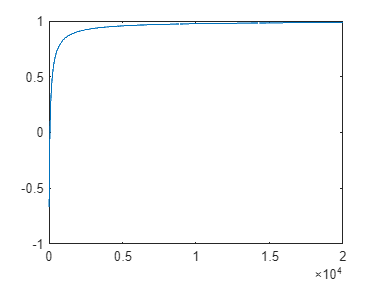

f = linspace(10, 20000, 20000 - 10 + 1);
sc = tanh(log10(f) - 1.8);
plot(f, sc);

So considering a cutoff frequency parameter $\rho_c \in \left\lbrack 0,1\right\rbrack$, $\varphi^{-1} \left(\rho_c \right)$ is expected to give a good perception of the cutoff frequency:


$$F_c ={10}^{\mathrm{atanh}\left(\rho_c \right)+1\ldotp 8}$$


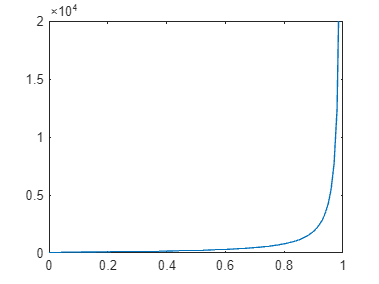

x = linspace(0, 1, 100);
xc = power(10, atanh(x) + 1.8);
plot(x, xc);
xlim([0 1]);
ylim([0 20000]);

Let $c\in \left\lbrack 0,127\right\rbrack$ be the cutoff frequency parameter, the corresponding ratio is $\rho_c =\frac{c}{127}$ and the translation to an actual frequency is:


$$F_c ={10}^{\mathrm{atanh}\left(\frac{c}{127}\right)+1\ldotp 8}$$


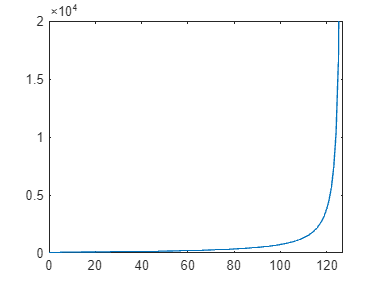

c = linspace(0, 127, 128);
fc = power(10, atanh(c/127) + 1.8);
plot(c, fc);
xlim([0 127]);
ylim([0 20000]);

TODO: this is worth a try but expensive computation. And you did not consider the lower limit of 10dBs.

#### Resonance

TODO

### High-pass filter

TODO